# Actividad 6.2 - Lazo abierto

Ana Itzel Hernández García 

Trayectoria con un robot tipo diferencial aplicando las técnicas: “**Lazo abierto**”

Limpieza de pantalla

clear 
close all
clc

Puntos deseados

x_vec = [-9, -7, -2, 3, 5, -9];
y_vec = [10, 1, -10, 1, 10, 10];

**Contron Lazo Abierto **

Parámetros del movimiento

ts = 0.01;       % Tiempo de muestreo
v = 10;         % Velocidad lineal
w = 10;         % Velocidad angular

 Inicialización del robot

x = x_vec(1); y = y_vec(1); theta = 0; % Posición y orientación inicial
x1 = []; y1 = []; phi = []; % Trayectoria simulada
hx = []; hy = [];          % Historia del centro del robot

for i = 1:(length(x_vec)-1)
    x_goal = x_vec(i+1);
    y_goal = y_vec(i+1);
    
    % ROTACIÓN EN EL LUGAR
    % Calcular el ángulo al objetivo
    angle_to_goal = atan2(y_goal - y, x_goal - x);
    
    % Calcular la diferencia de ángulos más corta
    angle_diff = angle_to_goal - theta;
    
    % Normalizar la diferencia de ángulos para estar en el rango [-pi, pi]
    angle_diff = mod(angle_diff + pi, 2*pi) - pi;
    
    % Calcular el tiempo necesario para rotar
    t_rot = abs(angle_diff) / w;  % Tiempo en segundos para llegar al ángulo
    
    % Actualizar la orientación del robot
    theta = theta + angle_diff;
    
    % Registrar la trayectoria
    x1(end+1) = x;
    y1(end+1) = y;
    phi(end+1) = theta;
    hx(end+1) = x;
    hy(end+1) = y;

    % Calcular la distancia al objetivo
    dist = sqrt((x_goal - x)^2 + (y_goal - y)^2);
    
    % Calcular el tiempo necesario para moverse hasta el objetivo
    t_trans = dist / v;  % Tiempo en segundos para cubrir la distancia
    
   % Movimiento lineal paso a paso
    n_steps = ceil(t_trans / ts); % Número de pasos
    for j = 1:n_steps
        x = x + v * cos(theta) * ts;
        y = y + v * sin(theta) * ts;
    
        % Registrar trayectoria paso a paso
        x1(end+1) = x;
        y1(end+1) = y;
        phi(end+1) = theta;
        hx(end+1) = x;
        hy(end+1) = y;
    end
end

k_global = length(x1);

** SIMULACIÓN VIRTUAL **

Configuración de escena

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

% Calcular rangos automáticamente basados en la trayectoria real
minX = min(x1) - 1;
maxX = max(x1) + 1;
minY = min(y1) - 1;
maxY = max(y1) + 1;

view(2); % Vista 2D
axis([minX maxX minY maxY 0 1]); % Rango ajustado a la trayectoria real


 Límites automáticos

xmin_lim = min(x_vec) - 2;
xmax_lim = max(x_vec) + 2;
ymin_lim = min(y_vec) - 2;
ymax_lim = max(y_vec) + 2;
axis([xmin_lim xmax_lim ymin_lim ymax_lim 0 1]);


Gráfica inicial

scale = 4;
MobileRobot_5; 
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
H3 = plot3(x_vec, y_vec, 0 * ones(size(x_vec)), 'bo', 'lineWidth', 2);
H4 = plot3(hx(1), hy(1), 0, 'go', 'lineWidth', 2);


 Animación

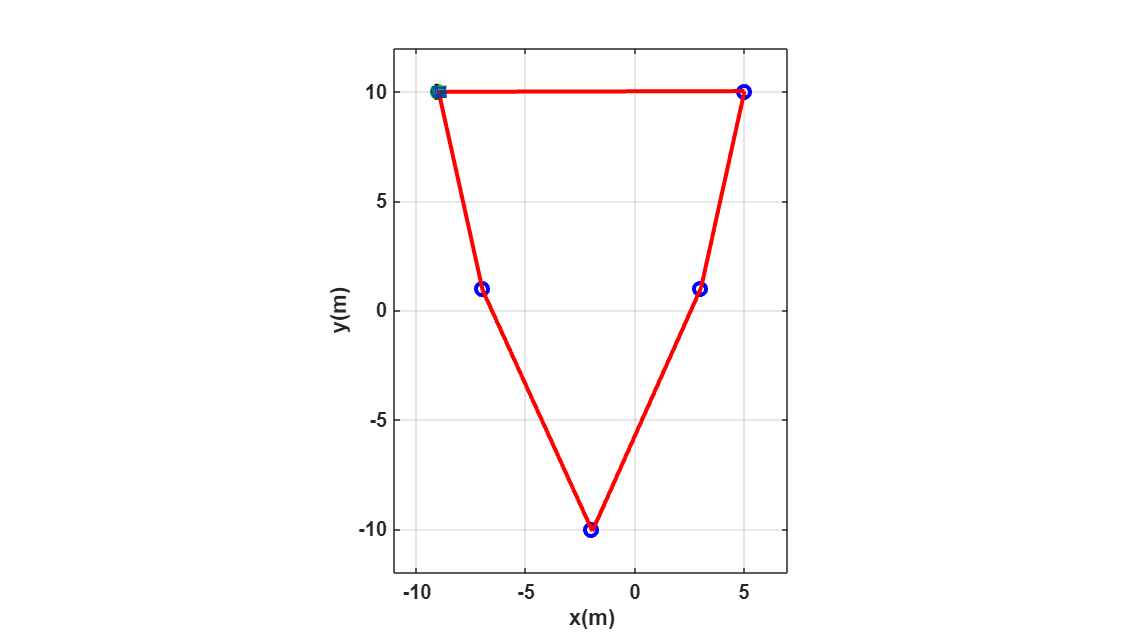

step = 1;
for k = 1:step:k_global
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end

**Ventajas:**

- La simplicidad ya que la implementación es directa 

- Cuenta con una eficiencia computacional al no necesitar estimación de errores, es decir, consume menos recursos.

- Funciona bien cuando el entorno es predecible y no hay perturbaciones.

**Desventajas:**

- No hay corrección de errores y cualquier desviación por ruido, errores en la estimación de posición o dinámicas no modeladas no será corregida, por lo tanto no se adapta a obstáculos o cambios

- Tiene una menor precisión, los errores de posición acumulados pueden alejar al robot de su trayectoria deseada.